# Modelo de Ball&Beam y control básico

Andrés Pantoja, Control por computador, Octubre 13 de 2020

#### Parámetros

Definición de Parámetros (en unidades del SI)

%clear; 
close all; clc;
r_arm=0.0254; L_beam=0.4255; g=9.8; kbb=5*g*r_arm/(7*L_beam);

#### Función de transferencia

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Sist1=kbb/s^2

Sist1 =
 
  0.4179
  ------
   s^2
 
Continuous-time transfer function.
Model Properties


#### Diseño de regulador por realimentación de estados

Linealización

syms x1 x2 u
f1=x2; f2=kbb*sin(u); f=[f1;f2];  % Definición del sistema
xs=[x1;x2];  % Vector de estados
As=jacobian(f,xs)   % Jacobiano con respecto a x

$$As = \left(\begin{array}{cc} 0 & 1\\ 0 & 0 \end{array}\right)$$

Bs=jacobian(f,u)    % Jacobiano con respecto a u

$$Bs = \left(\begin{array}{c} 0\\ \frac{1778\,\cos\left(u\right)}{4255} \end{array}\right)$$

xeq=[0 0]'; ueq=0;  % Punto de operación
A=double(subs(As,{x1,x2},xeq'))

A =      0     1
     0     0


B=double(subs(Bs,u,ueq))

B =          0
    0.4179


Diseño del controlador

polos=[-4.053+2.34*1i -4.053-2.34*1i]; % Polos Bessel orden 2
tsdes=3;    % Tiempo de asentamiento deseado
k=place(A,B,polos/tsdes)  % cálculo de ganancia de realimentación

k =     5.8239    6.4663


## Simulación con Resolución de ODE

Condiciones iniciales y periodo de muestreo

Tsim=10;            % Tiempo total de la simulación
pos_inic=0; vel_inic=0; x_0=[pos_inic vel_inic]';
Ts=0.2;             % Periodo de muestreo
Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
ref=0.2;
u=0;                % Señal de control para el primer instante de muestreo.
x=zeros(Ns,2); usim=zeros(Ns,1); % Tamaño de vectores definido

Ciclo de simulación

for i=1:Ns
    [t,xd]=ode45('plantafcn',Ts,x_0,[],kbb,u);   % Simular la planta para un Ts.
    xmed=xd(end,:)';  % Medir estados (la última señal se toma a los Ts segundos).
    u=-(k(1)*(xmed(1)-ref)+k(2)*xmed(2));       % Cálculo del control y se envía a la planta.
    x_0=xmed;        % Condiciones inciales para la próxima iteración
    x(i,:)=xmed';    % Solo almacenar los estados para graficar.
    usim(i,:)=u;     % Solo almacenar la señal de control para graficar.
end

Graficación

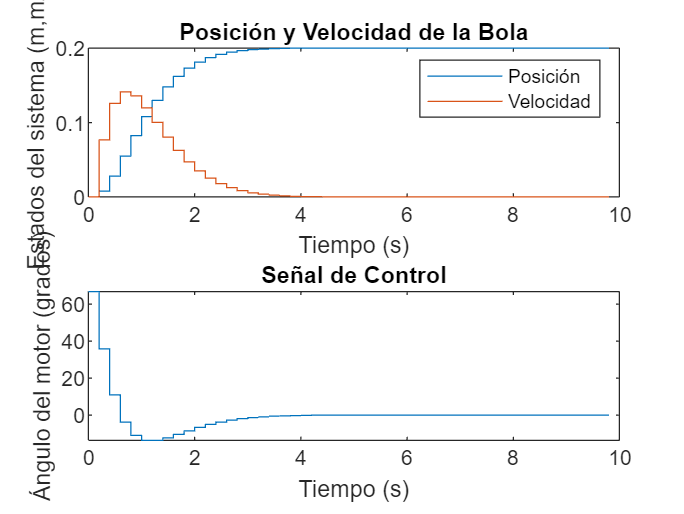

tdisc=0:Ts:Ns*Ts-Ts;
figure; subplot(2,1,1); stairs(tdisc,x); title('Posición y Velocidad de la Bola');
xlabel('Tiempo (s)'); ylabel('Estados del sistema (m,m/s)');
legend('Posición','Velocidad')
subplot(2,1,2); stairs(tdisc,usim*180/pi); title('Señal de Control');
xlabel('Tiempo (s)'); ylabel('Ángulo del motor (grados)');